clc ;
clear ;
close all ;



%constants 
syms m_r m_p                 real     %mass of the parts
syms J_r J_p                 real     %moment of inertia J_r is moment of In. around its end, J_p = moment of In around its COM
syms C_r C_p                 real     %damping constants
syms L_r L_p                 real     %lengths
syms g                      real     %gravity
syms K_t u K_m R_m         real %motor constants


syms t                        %time
syms alpha theta             real   %gen coordinates
syms alpha_dot theta_dot           real   %derivative of gen coordinates
syms alpha_ddot theta_ddot         real   %2nd derivates of gen cooridnates

syms v_p v_d                         real % velocity 
%syms omega_2 lambda

%generalized coordinates

q = [alpha ; theta]  ;
qd= [alpha_dot; theta_dot ]  ;
qdd= [alpha_ddot ; theta_ddot]  ;

% speed components of the masses

%v_r = [0 ; 0.5*L_r*alpha_dot;0]
v_r = [0;0;0];
%v_p = [0.5*L_p*sin(theta)*alpha_dot ; L_r*alpha_dot + 0.5*L_p*cos(theta)*theta_dot ; 0.5*L_p*sin(theta)*theta_dot] %a bit more complex 
v_p = [0;L_r*alpha_dot + 0.5*L_p*cos(theta)*theta_dot ; 0.5*L_p*sin(theta)*theta_dot];                             % simple version


**Lagrange to EOM**

% Lagrange to EOM

%% Energy functions
% kinetic energy function
T =1/2 * m_r*(v_r(1)^2 +v_r(2)^2+v_r(3)^2) + ...
   1/2 * m_p*(v_p(1)^2 +v_p(2)^2+v_p(3)^2) + ...
   1/2 * J_r * alpha_dot^2 + ...
   1/2 * J_p * theta_dot^2 ;

% potential energy function
V = 0.5*m_r*g*L_p*(1-cos(theta)) ;


% dissipation function
D= 1/2 * C_r * (alpha_dot)^2 + ...
   1/2 * C_p * (theta_dot)^2 ;

tau = K_t*(u -K_m*alpha_dot)/R_m

$$tau = \frac{K_{t}\,\left(u-K_{m}\,\dot{\alpha }\right)}{R_{m}}$$


%% Lagrangian
dT_dqd = simplify(jacobian(T,qd))'

$$dT\_dqd = \left(\begin{array}{c} J_{r}\,\dot{\alpha }+L_{r}\,m_{p}\,\left(L_{r}\,\dot{\alpha }+\frac{L_{p}\,\dot{\theta }\,\cos\left(\theta \right)}{2}\right)\\ \frac{m_{p}\,\dot{\theta }\,{L_{p}}^{2}}{4}+\frac{L_{r}\,\dot{\alpha }\,m_{p}\,\cos\left(\theta \right)\,L_{p}}{2}+J_{p}\,\dot{\theta } \end{array}\right)$$


DdT_Dtdqd = simplify(jacobian(dT_dqd,t)) + ...
           simplify(jacobian(dT_dqd,q))*qd + simplify(jacobian(dT_dqd,qd)) * qdd

$$DdT\_Dtdqd = \left(\begin{array}{c} -\frac{L_{p}\,L_{r}\,m_{p}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}}{2}+\ddot{\alpha }\,\left(m_{p}\,{L_{r}}^{2}+J_{r}\right)+\frac{L_{p}\,L_{r}\,m_{p}\,\ddot{\theta }\,\cos\left(\theta \right)}{2}\\ \ddot{\theta }\,\left(\frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}\right)+\frac{L_{p}\,L_{r}\,\ddot{\alpha }\,m_{p}\,\cos\left(\theta \right)}{2}-\frac{L_{p}\,L_{r}\,\dot{\alpha }\,m_{p}\,\dot{\theta }\,\sin\left(\theta \right)}{2} \end{array}\right)$$


dT_dq = simplify(jacobian(T,q))';

dV_dq = simplify(jacobian(V,q))'

$$dV\_dq = \left(\begin{array}{c} 0\\ \frac{L_{p}\,g\,m_{r}\,\sin\left(\theta \right)}{2} \end{array}\right)$$


dD_dqd =  simplify(jacobian(D,qd))'

$$dD\_dqd = \left(\begin{array}{c} C_{r}\,\dot{\alpha }\\ C_{p}\,\dot{\theta } \end{array}\right)$$


%% sanity check
L= T-V ;
dL_dqd = simplify(jacobian(L,qd))' 

$$dL\_dqd = \left(\begin{array}{c} J_{r}\,\dot{\alpha }+L_{r}\,m_{p}\,\left(L_{r}\,\dot{\alpha }+\frac{L_{p}\,\dot{\theta }\,\cos\left(\theta \right)}{2}\right)\\ \frac{m_{p}\,\dot{\theta }\,{L_{p}}^{2}}{4}+\frac{L_{r}\,\dot{\alpha }\,m_{p}\,\cos\left(\theta \right)\,L_{p}}{2}+J_{p}\,\dot{\theta } \end{array}\right)$$

DdL_DTdqd = simplify(jacobian(dL_dqd,t)) + ...
           simplify(jacobian(dL_dqd,q))*qd + simplify(jacobian(dL_dqd,qd)) * qdd

$$DdL\_DTdqd = \left(\begin{array}{c} -\frac{L_{p}\,L_{r}\,m_{p}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}}{2}+\ddot{\alpha }\,\left(m_{p}\,{L_{r}}^{2}+J_{r}\right)+\frac{L_{p}\,L_{r}\,m_{p}\,\ddot{\theta }\,\cos\left(\theta \right)}{2}\\ \ddot{\theta }\,\left(\frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}\right)+\frac{L_{p}\,L_{r}\,\ddot{\alpha }\,m_{p}\,\cos\left(\theta \right)}{2}-\frac{L_{p}\,L_{r}\,\dot{\alpha }\,m_{p}\,\dot{\theta }\,\sin\left(\theta \right)}{2} \end{array}\right)$$

dL_dq = simplify(jacobian(L,q))'

$$dL\_dq = \left(\begin{array}{c} 0\\ -\frac{L_{p}\,\sin\left(\theta \right)\,\left(g\,m_{r}+L_{r}\,\dot{\alpha }\,m_{p}\,\dot{\theta }\right)}{2} \end{array}\right)$$


%sanity check EOM
EOMtest = DdL_DTdqd - dL_dq +dD_dqd ;
EOMtest = simplify(EOMtest) - [tau ; 0]

$$EOMtest = \left(\begin{array}{c} C_{r}\,\dot{\alpha }+\ddot{\alpha }\,\left(m_{p}\,{L_{r}}^{2}+J_{r}\right)-\frac{K_{t}\,\left(u-K_{m}\,\dot{\alpha }\right)}{R_{m}}-\frac{L_{p}\,L_{r}\,m_{p}\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{2}+\frac{L_{p}\,L_{r}\,m_{p}\,\ddot{\theta }\,\cos\left(\theta \right)}{2}\\ C_{p}\,\dot{\theta }+J_{p}\,\ddot{\theta }+\frac{{L_{p}}^{2}\,m_{p}\,\ddot{\theta }}{4}+\frac{L_{p}\,g\,m_{r}\,\sin\left(\theta \right)}{2}+\frac{L_{p}\,L_{r}\,\ddot{\alpha }\,m_{p}\,\cos\left(\theta \right)}{2} \end{array}\right)$$




%EOM            
EOM = DdT_Dtdqd -  dT_dq + dV_dq + dD_dqd ; %Equation of motion
EOM_simplified = simplify(EOM) -[tau;0] %EOM added with the torque = C_t*tau

$$EOM\_simplified = \left(\begin{array}{c} C_{r}\,\dot{\alpha }+\ddot{\alpha }\,\left(m_{p}\,{L_{r}}^{2}+J_{r}\right)-\frac{K_{t}\,\left(u-K_{m}\,\dot{\alpha }\right)}{R_{m}}-\frac{L_{p}\,L_{r}\,m_{p}\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{2}+\frac{L_{p}\,L_{r}\,m_{p}\,\ddot{\theta }\,\cos\left(\theta \right)}{2}\\ C_{p}\,\dot{\theta }+\ddot{\theta }\,\left(\frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}\right)+\frac{L_{p}\,g\,m_{r}\,\sin\left(\theta \right)}{2}+\frac{L_{p}\,L_{r}\,\ddot{\alpha }\,m_{p}\,\cos\left(\theta \right)}{2} \end{array}\right)$$

**Linearizing EOM **

%Linearized at the bottom using sin(theta) = theta, cos(theta)= 1,
%and theta_dot^2= alpha_dot^2 = 0 ;
subin = {sin(theta), cos(theta), theta_dot^2, alpha_dot^2, alpha_dot*theta_dot};
subreplace_down = {theta, 1, 0, 0, 0};
subreplace_up   = {-theta, -1, 0, 0, 0};

EOM_down = subs(EOM_simplified,subin,subreplace_down) % Linearized down

$$EOM\_down = \left(\begin{array}{c} C_{r}\,\dot{\alpha }+\ddot{\alpha }\,\left(m_{p}\,{L_{r}}^{2}+J_{r}\right)-\frac{K_{t}\,\left(u-K_{m}\,\dot{\alpha }\right)}{R_{m}}+\frac{L_{p}\,L_{r}\,m_{p}\,\ddot{\theta }}{2}\\ C_{p}\,\dot{\theta }+\ddot{\theta }\,\left(\frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}\right)+\frac{L_{p}\,L_{r}\,\ddot{\alpha }\,m_{p}}{2}+\frac{L_{p}\,g\,m_{r}\,\theta }{2} \end{array}\right)$$


%Linearized at the top sin(theta+ pi) = -theta, cos(theta+pi)= -1,
%and theta_dot^2= alpha_dot^2 = 0

EOM_up = subs(EOM_simplified,subin,subreplace_up) % Linearized up

$$EOM\_up = \left(\begin{array}{c} C_{r}\,\dot{\alpha }+\ddot{\alpha }\,\left(m_{p}\,{L_{r}}^{2}+J_{r}\right)-\frac{K_{t}\,\left(u-K_{m}\,\dot{\alpha }\right)}{R_{m}}-\frac{L_{p}\,L_{r}\,m_{p}\,\ddot{\theta }}{2}\\ C_{p}\,\dot{\theta }+\ddot{\theta }\,\left(\frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}\right)-\frac{L_{p}\,L_{r}\,\ddot{\alpha }\,m_{p}}{2}-\frac{L_{p}\,g\,m_{r}\,\theta }{2} \end{array}\right)$$


%% Find out about which direction tau is at the lab..

**Linear equation to state space**

syms a_1

EOM_down = collect(EOM_down,{'u' 'alpha_dot' 'alpha_ddot' 'theta' 'theta_dot' 'theta_ddot'})

$$EOM\_down = \left(\begin{array}{c} \left(C_{r}+\frac{K_{m}\,K_{t}}{R_{m}}\right)\,\dot{\alpha }+\left(m_{p}\,{L_{r}}^{2}+J_{r}\right)\,\ddot{\alpha }+\frac{L_{p}\,L_{r}\,m_{p}}{2}\,\ddot{\theta }+\left(-\frac{K_{t}}{R_{m}}\right)\,u\\ \frac{L_{p}\,L_{r}\,m_{p}}{2}\,\ddot{\alpha }+\frac{L_{p}\,g\,m_{r}}{2}\,\theta +C_{p}\,\dot{\theta }+\left(\frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}\right)\,\ddot{\theta } \end{array}\right)$$


%terms in EOM_down(1)
a11 = (C_r + (K_m*K_t)/R_m)

$$a11 = C_{r}+\frac{K_{m}\,K_{t}}{R_{m}}$$

a12 = (m_p*L_r^2 + J_r) 

$$a12 = m_{p}\,{L_{r}}^{2}+J_{r}$$

a13 = ((L_p*L_r*m_p)/2)

$$a13 = \frac{L_{p}\,L_{r}\,m_{p}}{2}$$

a14 = (-K_t/R_m)

$$a14 = -\frac{K_{t}}{R_{m}}$$


%terms in EOM_down(2)
a21 = ((L_p*g*m_r)/2)

$$a21 = \frac{L_{p}\,g\,m_{r}}{2}$$

a22 = ((m_p*L_p^2)/4 + J_p)

$$a22 = \frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}$$


syms a_11 a_12 a_13 a_14 a_21 a_22 real 

suba_old = {a11, a12, a13, a14, a21, a22 };
suba_new_down  = {a_11, a_12, a_13, a_14, a_21, a_22}  ; % substitus for down position
suba_new_up    = {a_11, a_12, -a_13, a_14, -a_21, a_22} ;  % substitus for down position                                    


EOM_down1 = a_11*alpha_dot + a_12*alpha_ddot + a_13*theta_ddot + a_14*u ;
EOM_down2 =a_13*alpha_ddot + a_21*theta + C_p*theta_dot + a_22*theta_ddot;
EOM_down_new = [EOM_down1 ; EOM_down2]

$$EOM\_down\_new = \left(\begin{array}{c} a_{11}\,\dot{\alpha }+a_{12}\,\ddot{\alpha }+a_{13}\,\ddot{\theta }+a_{14}\,u\\ C_{p}\,\dot{\theta }+a_{13}\,\ddot{\alpha }+a_{21}\,\theta +a_{22}\,\ddot{\theta } \end{array}\right)$$


EOM_up_new = subs(EOM_down_new, suba_new_down, suba_new_up)

$$EOM\_up\_new = \left(\begin{array}{c} a_{11}\,\dot{\alpha }+a_{12}\,\ddot{\alpha }-a_{13}\,\ddot{\theta }+a_{14}\,u\\ C_{p}\,\dot{\theta }-a_{13}\,\ddot{\alpha }-a_{21}\,\theta +a_{22}\,\ddot{\theta } \end{array}\right)$$


%% solving the equation for downward state space
sol_down=solve(EOM_down_new==[0;0],[theta_ddot,alpha_ddot]) 

sol_down = struct with fields:
    theta_ddot: -(C_p*a_12*theta_dot - a_11*a_13*alpha_dot + a_12*a_21*theta - a_13*a_14*u)/(- a_13^2 + a_12*a_22)
    alpha_ddot: (C_p*a_13*theta_dot - a_11*a_22*alpha_dot + a_13*a_21*theta - a_14*a_22*u)/(- a_13^2 + a_12*a_22)


down_linearized=[alpha_ddot;theta_ddot]== [sol_down.alpha_ddot; sol_down.theta_ddot ] 

$$down\_linearized = \left(\begin{array}{c} \ddot{\alpha }=\frac{C_{p}\,a_{13}\,\dot{\theta }-a_{11}\,a_{22}\,\dot{\alpha }+a_{13}\,a_{21}\,\theta -a_{14}\,a_{22}\,u}{a_{12}\,a_{22}-{a_{13}}^{2}}\\ \ddot{\theta }=-\frac{C_{p}\,a_{12}\,\dot{\theta }-a_{11}\,a_{13}\,\dot{\alpha }+a_{12}\,a_{21}\,\theta -a_{13}\,a_{14}\,u}{a_{12}\,a_{22}-{a_{13}}^{2}} \end{array}\right)$$


%% solving the equation for upward state space
sol_up=solve(EOM_up_new==[0;0],[theta_ddot,alpha_ddot]) 

sol_up = struct with fields:
    theta_ddot: -(C_p*a_12*theta_dot + a_11*a_13*alpha_dot - a_12*a_21*theta + a_13*a_14*u)/(- a_13^2 + a_12*a_22)
    alpha_ddot: -(C_p*a_13*theta_dot + a_11*a_22*alpha_dot - a_13*a_21*theta + a_14*a_22*u)/(- a_13^2 + a_12*a_22)


up_linearized=[alpha_ddot;theta_ddot]== [sol_up.alpha_ddot; sol_up.theta_ddot ] 

$$up\_linearized = \left(\begin{array}{c} \ddot{\alpha }=-\frac{C_{p}\,a_{13}\,\dot{\theta }+a_{11}\,a_{22}\,\dot{\alpha }-a_{13}\,a_{21}\,\theta +a_{14}\,a_{22}\,u}{a_{12}\,a_{22}-{a_{13}}^{2}}\\ \ddot{\theta }=-\frac{C_{p}\,a_{12}\,\dot{\theta }+a_{11}\,a_{13}\,\dot{\alpha }-a_{12}\,a_{21}\,\theta +a_{13}\,a_{14}\,u}{a_{12}\,a_{22}-{a_{13}}^{2}} \end{array}\right)$$



%% converting to SS

ssvars=[alpha,theta,alpha_dot,theta_dot,u];
sys_lin0=simplify([
    0,0,1,0,0
    0,0,0,1,0
    matrixinsert(sol_down.alpha_ddot,ssvars)
    matrixinsert(sol_down.theta_ddot,ssvars)
    1,0,0,0,0
    0,1,0,0,0
])

$$sys\_lin0 = \begin{array}{l} \left(\begin{array}{ccccc} 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & \frac{a_{13}\,a_{21}}{\sigma_{1}} & -\frac{a_{11}\,a_{22}}{\sigma_{1}} & \frac{C_{p}\,a_{13}}{\sigma_{1}} & -\frac{a_{14}\,a_{22}}{\sigma_{1}}\\ 0 & -\frac{a_{12}\,a_{21}}{\sigma_{1}} & \frac{a_{11}\,a_{13}}{\sigma_{1}} & -\frac{C_{p}\,a_{12}}{\sigma_{1}} & \frac{a_{13}\,a_{14}}{\sigma_{1}}\\ 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{12}\,a_{22}-{a_{13}}^{2} \end{array}$$


sys_linpi=simplify([
    0,0,1,0,0
    0,0,0,1,0
    matrixinsert(sol_up.alpha_ddot,ssvars)
    matrixinsert(sol_up.theta_ddot,ssvars)
    1,0,0,0,0
    0,1,0,0,0
])

$$sys\_linpi = \begin{array}{l} \left(\begin{array}{ccccc} 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & \frac{a_{13}\,a_{21}}{\sigma_{1}} & -\frac{a_{11}\,a_{22}}{\sigma_{1}} & -\frac{C_{p}\,a_{13}}{\sigma_{1}} & -\frac{a_{14}\,a_{22}}{\sigma_{1}}\\ 0 & \frac{a_{12}\,a_{21}}{\sigma_{1}} & -\frac{a_{11}\,a_{13}}{\sigma_{1}} & -\frac{C_{p}\,a_{12}}{\sigma_{1}} & -\frac{a_{13}\,a_{14}}{\sigma_{1}}\\ 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{12}\,a_{22}-{a_{13}}^{2} \end{array}$$



sys_lin0 = subs(sys_lin0,suba_new_down,suba_old)

$$sys\_lin0 = \begin{array}{l} \left(\begin{array}{ccccc} 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & \frac{{L_{p}}^{2}\,L_{r}\,g\,m_{p}\,m_{r}}{4\,\sigma_{2}} & -\frac{\sigma_{3}\,\sigma_{1}}{\sigma_{2}} & \frac{C_{p}\,L_{p}\,L_{r}\,m_{p}}{2\,\sigma_{2}} & \frac{K_{t}\,\sigma_{3}}{R_{m}\,\sigma_{2}}\\ 0 & -\frac{L_{p}\,g\,m_{r}\,\sigma_{4}}{2\,\sigma_{2}} & \frac{L_{p}\,L_{r}\,m_{p}\,\sigma_{1}}{2\,\sigma_{2}} & -\frac{C_{p}\,\sigma_{4}}{\sigma_{2}} & -\frac{K_{t}\,L_{p}\,L_{r}\,m_{p}}{2\,R_{m}\,\sigma_{2}}\\ 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{r}+\frac{K_{m}\,K_{t}}{R_{m}}\\ \sigma_{2}=\sigma_{3}\,\sigma_{4}-\frac{{L_{p}}^{2}\,{L_{r}}^{2}\,{m_{p}}^{2}}{4}\\ \sigma_{3}=\frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}\\ \sigma_{4}=m_{p}\,{L_{r}}^{2}+J_{r} \end{array}$$

sys_linpi =subs(sys_linpi,suba_new_down,suba_old)

$$sys\_linpi = \begin{array}{l} \left(\begin{array}{ccccc} 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & \frac{{L_{p}}^{2}\,L_{r}\,g\,m_{p}\,m_{r}}{4\,\sigma_{2}} & -\frac{\sigma_{3}\,\sigma_{1}}{\sigma_{2}} & -\frac{C_{p}\,L_{p}\,L_{r}\,m_{p}}{2\,\sigma_{2}} & \frac{K_{t}\,\sigma_{3}}{R_{m}\,\sigma_{2}}\\ 0 & \frac{L_{p}\,g\,m_{r}\,\sigma_{4}}{2\,\sigma_{2}} & -\frac{L_{p}\,L_{r}\,m_{p}\,\sigma_{1}}{2\,\sigma_{2}} & -\frac{C_{p}\,\sigma_{4}}{\sigma_{2}} & \frac{K_{t}\,L_{p}\,L_{r}\,m_{p}}{2\,R_{m}\,\sigma_{2}}\\ 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{r}+\frac{K_{m}\,K_{t}}{R_{m}}\\ \sigma_{2}=\sigma_{3}\,\sigma_{4}-\frac{{L_{p}}^{2}\,{L_{r}}^{2}\,{m_{p}}^{2}}{4}\\ \sigma_{3}=\frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p}\\ \sigma_{4}=m_{p}\,{L_{r}}^{2}+J_{r} \end{array}$$



%parameters 

L_p = 0.129 %meters

L_p =         0.129


L_r = 0.085 %meters 

L_r =         0.085


m_p = 0.024 %kg 

m_p =         0.024


m_r = 0.095 %kg

m_r =         0.095


J_p = 1/12*m_p*L_p^2

J_p =    3.3282e-05


J_r = 1/3*m_r*L_r^2

J_r =    0.00022879


%J_p = 3.3e-5
%J_r = 5.7e-5
C_p = 0.0005 

C_p =        0.0005


C_r = 0.0015

C_r =        0.0015



R_m = 8.4 %ohm

R_m =           8.4


K_t = 0.042 % Nm/A

K_t =         0.042


K_m = 0.042 %Vs/rad

K_m =         0.042



g = 9.81 

g =          9.81



%% STATE SPACE
Down_SS_ABCD=double(subs(sys_lin0))

Down_SS_ABCD =             0            0            1            0            0
            0            0            0            1            0
            0       218.31      -6.2835       1.8159       18.373
            0       -667.3       6.2104      -5.5506      -18.159
            1            0            0            0            0
            0            1            0            0            0


Up_SS_ABCD=double(subs(sys_linpi))

Up_SS_ABCD =             0            0            1            0            0
            0            0            0            1            0
            0       218.31      -6.2835      -1.8159       18.373
            0        667.3      -6.2104      -5.5506       18.159
            1            0            0            0            0
            0            1            0            0            0



sys_down = ss(Down_SS_ABCD(1:4,1:4), Down_SS_ABCD(1:4,5), Down_SS_ABCD(5:end,1:4), Down_SS_ABCD(5:end,5))

sys_down =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0   218.3  -6.283   1.816
   x4       0  -667.3    6.21  -5.551
 
  B = 
           u1
   x1       0
   x2       0
   x3   18.37
   x4  -18.16
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



sys_up = ss(Up_SS_ABCD(1:4,1:4), Up_SS_ABCD(1:4,5), Up_SS_ABCD(5:end,1:4), Up_SS_ABCD(5:end,5))

sys_up =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0   218.3  -6.283  -1.816
   x4       0   667.3   -6.21  -5.551
 
  B = 
          u1
   x1      0
   x2      0
   x3  18.37
   x4  18.16
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



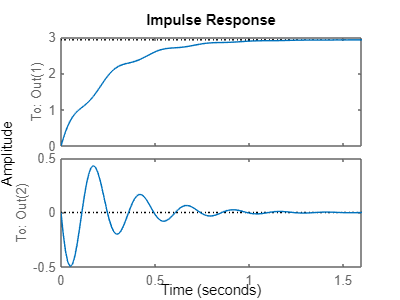


impulse(sys_down)

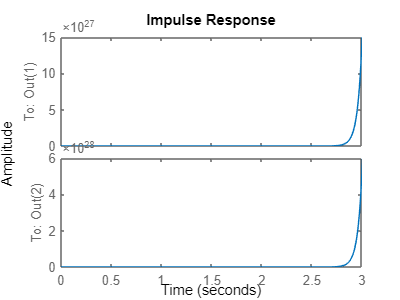

impulse(sys_up)

## previous obtained ss



% upside = [600.9444 , -2.1196 , 50.4674 ; 1048,-2.0994,49.9864 ] 
% down = [600.9444, - 2.1196, 50.4674 ; -1048 ,2.0994, -49.9864]
% A_down = [0 0 1 0; 0 0 0 1 ; 0 down(1,[1 2]) 0; 0 down(2,[1 2]) 0] ;
% B_down = [0;0;down(:,3)];
% C= [eye(2) zeros(2)]; 
% D = zeros(2,1) ;
% sys = ss(A_down,B_down,C,D);
% impulse(sys)
% A_down(4,:) = - A_down(4,:)
% B_down(4) = -B_down(4)
% sys_up = ss(A_down,B_down,C,D)
% %impulse(sys_up)

% A_down(4,:) = - A_down(4,:)
% B_down(4) = -B_down(4)
% sys_up = ss(A_down,B_down,C,D)
% %impulse(sys_up)



